# F2_Run_1D_Sensitivity.m

**Goal: **Generate 1D sensitivity analysis on probiotic parameters starting with the "null" probiotic. The "null" probiotic is defined as having a moderate growth rate (0.5) and all interspecies interaction terms as zero.

**Requirements:** 

MATLAB Toolboxes: Parallel Computing, Bioinformatics, Symbolic Math

Custom Scripts: Add the `probiotic_code/` folder to your path

Model inputs as defined in `define_Common_Simulation_Inputs `(*Defines virtual patient population, simulation inputs)*

*Functions:*` simulate_CST_probiotic_object.m, plot_1D_SensitivityAnalysis`

**Output:** Workspace with results of 1D analysis. 

**Time Demand:** High, can take several hours to finish runnning (including parallel computing, Windows 10)

## 1. Load Model Defaults

clear; clc;
output_fdr = 'result_workspaces/F2/'; % update as needed for the location of your output files
ws_name = 'input_files/SSConfig-Analysis-HMP-Virtual-Population.mat';
simulationType = "base";
[POPinfo,PROBinfo,~,SIMinfo] = define_Common_Simulation_Inputs(ws_name,simulationType);
[param_names,~,sp_cols,~] = get_naming_terms();

`POPinfo`: struct that defines virtual patient population

- `virtualPatientParameter`s: # patients x 20 parameter matrix generated by LHS

- `virtualPatientComposition`: 1 x # patients cell of analytically predicted steady-state absolute abundances of nAB, Li, oLB (predicted without considering probiotic in community)

`PROBinfo`: struct that defines probiotic parameters

- `dose`: absolute abundance of probiotic when dosed into the base community (selected from relative abundance data observed in Dausset et al. 2018)

- `numberDoses`: total number of doses given

- `doseFrequency`: time separation (days) between each dose

`SIMinfo`: struct that defines simulation inputs

- `startProbiotic`: time point after simulation begins to start probiotic therapy

- `stopSimulation`: time point to end simulation relative to the last day of probiotic treatment

- ` initialComposition`: scaling factor to "displace" from the predicted composition (POPinfo.virtualPatientComposition). For example, 0.01 is a 1% decrease in abundance and 0.05 is a 0.5% increase from the predicted abundance

- `alteredParamIndex`: indexes of probiotic-related parameters relative to the full parameter list

- `paramAlteration`: new value for probiotic parameters (a 1 x length alteredParamIndex array of values)

- `paramAlterationType`: 'None' (use LHS probiotic parameter, ignore paramAlteration values), 'fold addition' (scale LHS probiotic parameter (LP) + paramAlteration * LP,  'absolute' (set to exact value in paramAlteration)

- `ODEoptions`: "options" input for ode solvers

- `ODEsolver:` ODE solver function handle (e.g., @ode45, @ode15s)

## 2. Run 1D Sensivity Analysis

Define the inputs of the 1D sensitivity analysis. Here, we used a linear range of parameter values for the growth rate and the interspecies interaction terms. A logspace was used for the intra-species (ii) term, which describes the carrying capacity of the probiotic. For this analysis, a log scale was selected as abundance can change over several log values.

% DEFINE THE 1D PARAMETER INFO TO ALTER 
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
base_params = [0.5 0 0 0 0 0 0 -0.022]; % null probiotic as base
n = 21; % number of iterationss
param_alterkg = linspace(0,1,n); % growth rate parameter range
param_alteris = linspace(-0.1,0.1,n); % interspecies interaction parameter range
param_alterii = -logspace(log10(0.004),log10(0.04),n); % interspecies interaction parameter range
output_ws_nm = 'F2_1D_Sensitivity.mat';


The code below iterates through the all the parameters and the parameter values in the parameter ranges, one at a time (OAT). This is a local sensitivity analysis and is centered in the parameter space to the null probiotic strain values. **Took 73 minutes to run.**

% RUN SIMULATION FOR ALL ITERATIONS OF PARAMETER CHANGES 
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
numVirtualPatients = length(POPinfo.virtualPatientComposition);
all_select_outcomes = NaN(length(base_params),length(param_alterkg),numVirtualPatients,8,5);
all_warnall = NaN(length(base_params),length(param_alterkg),numVirtualPatients);
t = tic;
for param_id = 1:length(SIMinfo.alteredParamIndex)
    if param_id == 1
        param_alter = param_alterkg;
    elseif param_id == length(SIMinfo.alteredParamIndex)
        param_alter = param_alterii;
    else
        param_alter = param_alteris;
    end
    for pert_id = 1:length(param_alter)
        SIMinfo.paramAlteration = base_params;
        SIMinfo.paramAlteration(param_id) = param_alter(pert_id);
        [select_outcomes,nonBVflag,tall,yall,warnall,...
           dose_lbls] = simulate_CST_probiotic_object(POPinfo,PROBinfo,SIMinfo);

        all_select_outcomes(param_id,pert_id,:,:,:) = select_outcomes;
        all_warnall(param_id,pert_id,:) = warnall == "";


        disp(strcat("Parameter #",num2str(param_id), " iterations #",num2str(pert_id)))
    end
    save(strcat(output_fdr,output_ws_nm),'all_select_outcomes','all_warnall',...
        'POPinfo','PROBinfo','SIMinfo','base_params',...
        'param_alterkg','param_alteris','param_id','pert_id',...
        'sp_cols','param_names','param_alterii')
    pause(60*3) % pause for 3 minutes
end

> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #1


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #2


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #3


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #4


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #5


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #6


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #7


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #8


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #9


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #10


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #11


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #12


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #13


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #14


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #15


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #16


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #17


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #18


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #19


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #20


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #1 iterations #21


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #1


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #2


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #3


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #4


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #5


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #6


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #7


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #8


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #9


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #10


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #11


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #12


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #13


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #14


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #15


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #16


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #17


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #18


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #19


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #20


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #2 iterations #21


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #1


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #2


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #3


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #4


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #5


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #6


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #7


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #8


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #9


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #10


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #11


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #12


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #13


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #14


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #15


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #16


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #17


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #18


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #19


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #20


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #3 iterations #21


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #1


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #2


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #3


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #4


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #5


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #6


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #7


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #8


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #9


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #10


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #11


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #12


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #13


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #14


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #15


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #16


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #17


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #18


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #19


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #20


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #4 iterations #21


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #5 iterations #1


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #5 iterations #2


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #5 iterations #3


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #5 iterations #4


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #5 iterations #5


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #5 iterations #6


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #5 iterations #7


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #5 iterations #8


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #5 iterations #9


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #5 iterations #10


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #5 iterations #11


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #5 iterations #12


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #5 iterations #13
Parameter #5 iterations #14


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #5 iterations #15


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #5 iterations #16
Parameter #5 iterations #17
Parameter #5 iterations #18


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #5 iterations #19


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #5 iterations #20
Parameter #5 iterations #21


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #1


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #2


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #3


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #4


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #5


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #6


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #7


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #8


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #9


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #6 iterations #10


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #6 iterations #11


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #12


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #13


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #14


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #15


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #16


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #17


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #18


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #19


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #20


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #6 iterations #21


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #7 iterations #1


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #7 iterations #2


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #7 iterations #3


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #7 iterations #4


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #7 iterations #5


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #7 iterations #6
Parameter #7 iterations #7
Parameter #7 iterations #8
Parameter #7 iterations #9
Parameter #7 iterations #10


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #7 iterations #11


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #7 iterations #12


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #7 iterations #13


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #7 iterations #14


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #7 iterations #15


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #7 iterations #16


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #7 iterations #17


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #7 iterations #18


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #7 iterations #19


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #7 iterations #20


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Parameter #7 iterations #21


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #1


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #2


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #3


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #4


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #5


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #6


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #7


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #8


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #9


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #10


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #11


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #12


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #13


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #14


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #15


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #16


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #17


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #18


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #19


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #20


> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)


Parameter #8 iterations #21


tend = toc(t);
disp(strcat(num2str(tend/60)," minutes"))

73.5759 minutes


Outputs saved include:

- `all_select_outcomes`: 5D array [# parameters altered x # perturbations x # subjects x # evaluations points x # model speices + 1]. In this example it would be an 8 x 21 x 2000 x 8 x 5 double. Default number of evaluation points is 8 (time points where abundance measurement is collected, the last dimension is the time point and the species abundance. 

- `nonBVflag`: logica that indicates if the run is not nAB dominant when the probiotic is added

- `all_warnall`: 3D array [# parameters altered x # perturbations x # subjects], index of 1 means no ODE solver warning, index of 0 indicates there was a integration warning

- `base_params`: parameter set the 1D analysis was centered around

- `param_alterkg`: array with each alteration value for kgrow-P

- `param_alteris`: array with each alteration value for all inter-species interaction terms (nAB->P, Li->P, oLB->P, P->nAB, P->Li, P->oLB)

- `param_alterii:` array with each alteration value for all intra-species (self) interaction terms (P->P)

- `sp_cols`: array describing default colors in order of nAB, Li, oLB, P.

## 3. Plot Result

This code plots the result (frequency of each response type) for each parameter, over each iteration of the parameter alterations, evaluated at time_id. 

The time_id = 8 is the index of `all_select_outcomes` corresponding with 12mo post therapy cessation. Other time points may be evaluated. To check the index of the desired time point, look at the cell array "`time_names`".

The most sensitive parameters are nAB -> P and P -> nAB. Growth rate and carrying capacity (P->P) were also important, as expected.

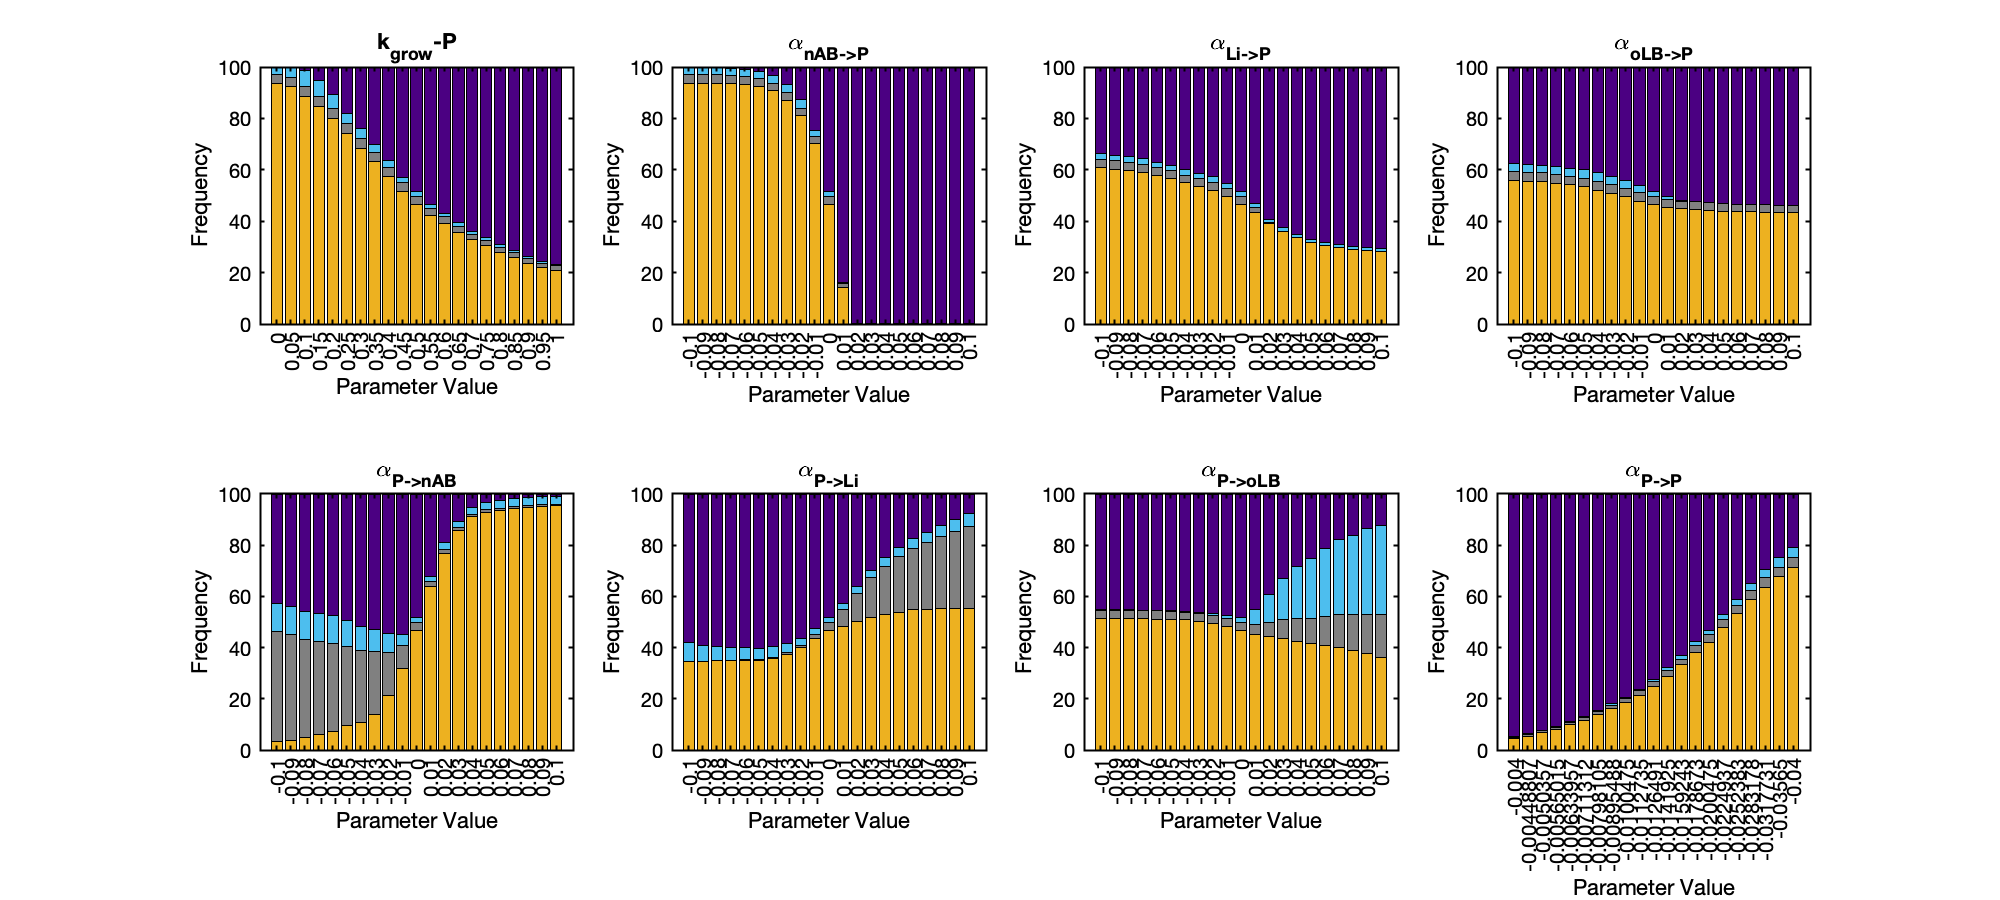

output_fdr = 'result_workspaces/F2/'; % update to your workspace out location 
load(strcat(output_fdr,'F2_1D_Sensitivity.mat'))
time_id = 8; % time point to evaluate
params_to_view = SIMinfo.alteredParamIndex;
figFlag = false; % true: plot parameters separately; false: subplot

[param_names,SSnms,sp_cols,time_names] = get_naming_terms();

f = figure;
plot_1D_SensitivityAnalysis(all_select_outcomes,all_warnall,time_id,...
    params_to_view,param_alterkg,param_alteris,param_alterii,param_names,SSnms,sp_cols,figFlag)
hLeg=findobj(f,'type','legend'); % remove legend
set(hLeg,'visible','off')
set(f,'Visible','on','units','pixels','position',[1 1 1000 450])